**1**. Implementieren Sie ein MATLAB-Skript, das für ein gegebenes Eingangsbild sämtliche Schritte der Hough-Transformation visualisiert, d.h. insbesondere das binäre **Kantenbild**, den **Hough-Raum**, und die in das Originalbild projizierten **Geradensegmente**. Falls nötig, finden Sie in der MATLAB Hilfe ein Code-Beispiel, auf dem Sie aufbauen können.

实现一个MATLAB脚本，将给定输入图像的Hough变换的所有步骤可视化，即特别是二进制边缘图像、Hough空间和投射到原始图像的直线段。如果有必要，你可以在MATLAB的帮助中找到一个代码例子来进行借鉴。

MATLAB bietet Funktionen zur Durchführung einer Hough-Transformation für gerade Linienelemente. Diese Funktionen sind:

`[H, theta, rho] = hough(BW) - `Berechnet die Hough-Transformierte aus einem Binärbild.

`peaks = houghpeaks(H, numpeaks) - `Sucht Höchstwerte im Hough-Raum

`lines = houghlines(BW, theta, rho, peaks) - `Bildet mit Hilfe der gefundenen Geraden und des Binärbilds zugehörige Geradensegmente

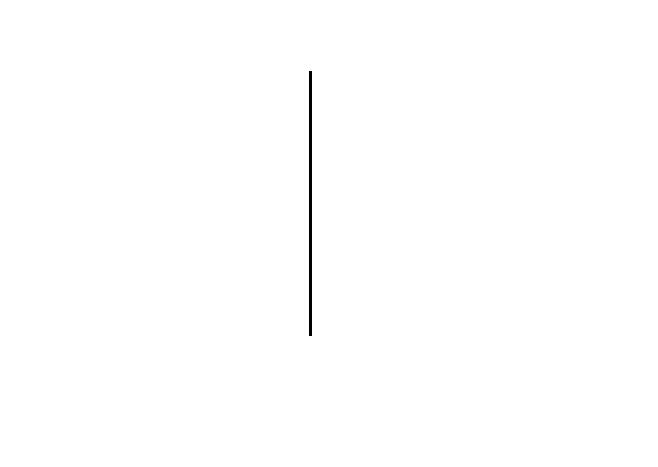

clc;
close all;
filePath='../Bilder/';%%图片所在的目录
fileDir=dir(fullfile(filePath));
fileNames={fileDir.name};%%将filePath下所有文件的文件名存于元胞数组fileNames中
judgeFolder={fileDir.isdir};%%判断是否为文件夹
for i=1:length(judgeFolder)
    if(judgeFolder{1,i}==1)
       fileNames(1,i)={'0'};%%是文件夹就将其替换为'0'，为了删除文件名为xx.jpg等类似的文件夹
    end
end
for i=1:length(fileNames)
    cellFile=fileNames(i);
    stringFile=char(cellFile);
    stringLength=length(stringFile);
    if(stringLength>=5)%%一般图片文件名为x.jpg等，最少长度为5
            fileSuffix=strcat(stringFile(stringLength-3),stringFile(stringLength-2),stringFile(stringLength-1),stringFile(stringLength-0));%%将提取的单个后缀字符拼接起来
            if(strcmp(fileSuffix,'.bmp')==1||strcmp(fileSuffix,'.jpg')==1)%%字符串比较 输出指定类型的文件 
                src = imread(strcat(filePath,stringFile));
                figure,imshow(src);
            end

    end
end


binäres Kantenbild:

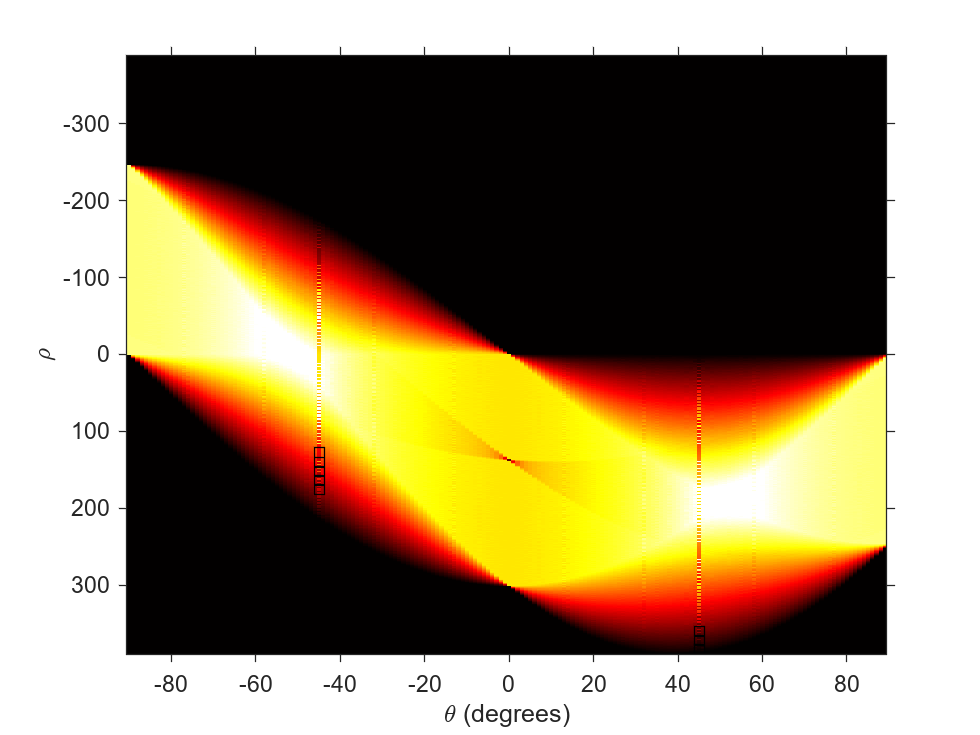

% Input_path = '../Bilder/';
% namelist = dir(strcat(Input_path,'*.png'));  %获得文件夹下所有的 .jpg图片
% len = length(namelist);
% name = namelist(1).name;
% % figure
% I =imread(strcat(Input_path, name));
% BW = imbinarize(I,0.5);
% rotI = imrotate(I,33,'crop');
% % montage(I,1,[1 NaN]);
% imshow(rotI);
% BW = edge(BW,'canny');
% for i = 3:len
%     name=namelist(i).name;  %namelist(i).name; %这里获得的只是该路径下的文件名
%     I=imread(strcat(Input_path, name)); %图片完整的路径名
%     montage(I,1,[1 NaN]);
%     title(i-2);%图片的显示
%     

% %     K2=wiener2(I,[5 5]); %对图片进行去噪处理
% %     imwrite(K2,[Output_path,'wie',int2str(i),'.jpg']); %完整的图片存储的路径名  并将整形的数字转换成字符串                                              
% end
% I1 = imread('Test_Bild1.png');
% I2 = imread('Test_Bild2.png');
% I3 = imread('Test_Bild3.png');
% I4 = imread('Test_Bild4.png');
% I5 = imread('Test_Bild5.png');
% I6 = imread('Test_Bild6.png');
% I7 = imread('Test_Bild7.png');
% % I7 = imread('Test_Bild7.png');
% BW1 = im2gray(I1);
% BW2 = im2gray(I2);
% BW3 = im2gray(I3);
% BW4 = im2gray(I4);
% BW5 = im2gray(I5);
% BW6 = im2gray(I6);
% BW7 = im2gray(I7);
% BW8 = im2gray(I1);
% BW9 = im2gray(I1);

Matlab example

% I = imread('circuit.tif');
% rotI = imrotate(I,33,'crop');
imshow(I1);
% BW = edge(rotI,'canny');
% imshow(BW);
[H1,theta1,rho1] = hough(BW1);
figure
imshow(imadjust(rescale(H1)),[],...
       'XData',theta,...
       'YData',rho,...
       'InitialMagnification','fit');
xlabel('\theta (degrees)')
ylabel('\rho')
axis on
axis normal 
hold on
colormap(gca,hot)

- peaks = houghpeaks(H, numpeaks, Name, Value)

- H: Hough transform matrix

- numpeaks: Maximum number of peaks to identify 指定要识别的最大峰值个数

- Threshold: Minimum value to be considered a peak: 0.5*max(H(:)) (default) 被视为峰值的最小值，指定为非负数。

- NHoodSize: Size of suppression neighborhood 隐藏邻域的大小，指定为由正奇数组成的二元素向量。*隐藏邻域*是每个峰值周围的邻域，在识别出峰值后，该域内的值会设置为零。`NHoodSize` 的默认值为大于或等于 `size(H)/50` 的最小奇数值。`NHoodSize` 的维数必须小于 Hough 变换矩阵 [`H`](https://ww2.mathworks.cn/help/images/ref/houghpeaks.html?searchHighlight=houghpeaks&s_tid=srchtitle_houghpeaks_1#buw9d0p-1-H) 的大小。

P_1 = houghpeaks(H1,8,'threshold',ceil(0.3*max(H(:))));
% P_2 = houghpeaks(H,6,'threshold',ceil(0.3*max(H(:))));
x_1 = theta(P_1(:,2));
y_1 = rho(P_1(:,1));
plot(x_1,y_1,'s','color','black');
% x_2 = theta(P_2(:,2));
% y_2 = rho(P_2(:,1));
% plot(x_2,y_2,'s','color','red');

Hough-Raum:

% [H, theta, rho] = hough(I);
% peaks = houghpeaks(H, numpeaks)
% lines = houghlines(BW, theta, rho, peaks)

in das Originalbild projizierte Geradensegmente:

Testen Sie die grundlegende Funktionsweise Ihres Programms anhand der Bilderserie „Test_Bild....png“. Versuchen Sie dabei die einzelnen Teilergebnisse und deren Zustandekommen nachzuvollziehen.

Recherchieren Sie die Funktionsweise der nachfolgend aufgelisteten Parameter und untersuchen Sie deren Einfluss auf das Ergebnis:

a.    Eigenschaften des Canny-Filters

Canny 方法与其他边缘检测方法的不同之处在于，它使用两种不同阈值（用于检测强边缘和弱边缘），并且仅当弱边缘连通到强边缘时才在输出中包括弱边缘。因此，这种方法不太可能受到噪声的影响，更可能检测到真正的弱边缘。

b.    Auflösung von rho und theta

c.    Anzahl und Schwellwert der zu findenden Maximalwerte im Hough-Raum

d.    Größe der Nachbarschaft, in der weitere Extremwerte unterdrückt werden 抑制进一步极端值的邻域的大小

e     Die Mindestlänge und maximale Lückengröße zur Bildung der Geradensegmente 形成直线段的最小长度和最大间隙尺寸

Diskutieren Sie den Effekt der einzelnen Parameter! 

**2**. Versuchen Sie nun, sämtliche Kanten im Bild „Platte1.png“ als Geradensegmente zu erkennen. Welche Segmente bereiten besondere Schwierigkeiten? Warum?

binäres Kantenbild:

Hough-Raum:

in das Originalbild projizierte Geradensegmente:

**Bonus:**

Wenden Sie Ihr in Aufgabe 2 angepasstes Skript zunächst ohne weitere Veränderungen auf das Bild „Platte2.png“ an. Diskutieren Sie das Ergebnis und schlagen Sie möglichst begründet Parameteränderungen vor, mit denen erneut sämtliche Geradensegmente hervorgehoben werden können.